# Create and Customize 3-D Surface Lighting Using surfl

`surfl` creates surface plots with colormap-based lighting.

### Create Data

Use the peaks function to generate data for visualization.

[X,Y,Z] = peaks(100);

### Basic Surface with Lighting Plot

View the surface generated from the peaks function. The surface uses Z for height and both Z and the light source for color.

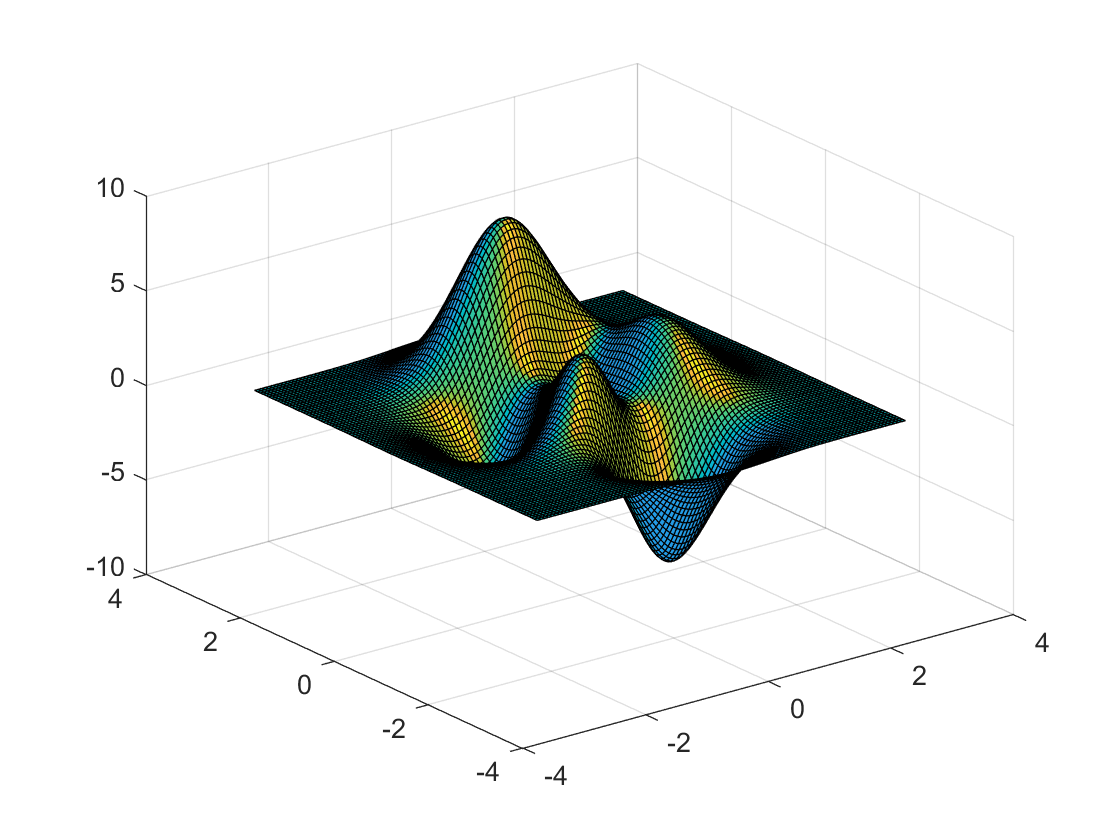

surfl(X,Y,Z);

## Customization

### Modify Light Object

The function returns an array containing a Surface object and a Light object if *'light'* is used as a 4th input to `surfl`. Assign it to the variable *sl*.

sl = surfl(X,Y,Z,"light");

The Surface object is accessible as sl(1) and the Light object as sl(2). For example, change the color of the light by setting the *Color* property of the Light object.

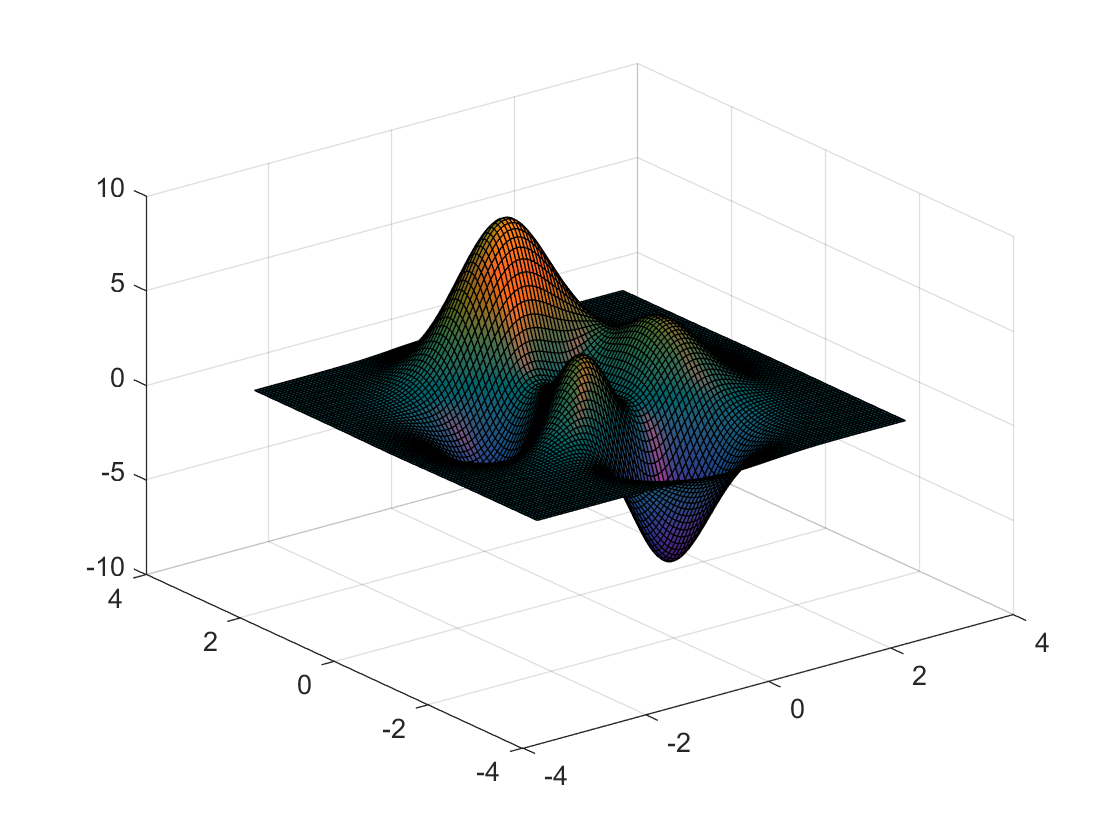

sl(2).Color = 'r';

### Change Chart Colormap

There are several default colormaps specified in MATLAB, some are shown in the drop down menu. Specify a colormap to use in `surfl`.

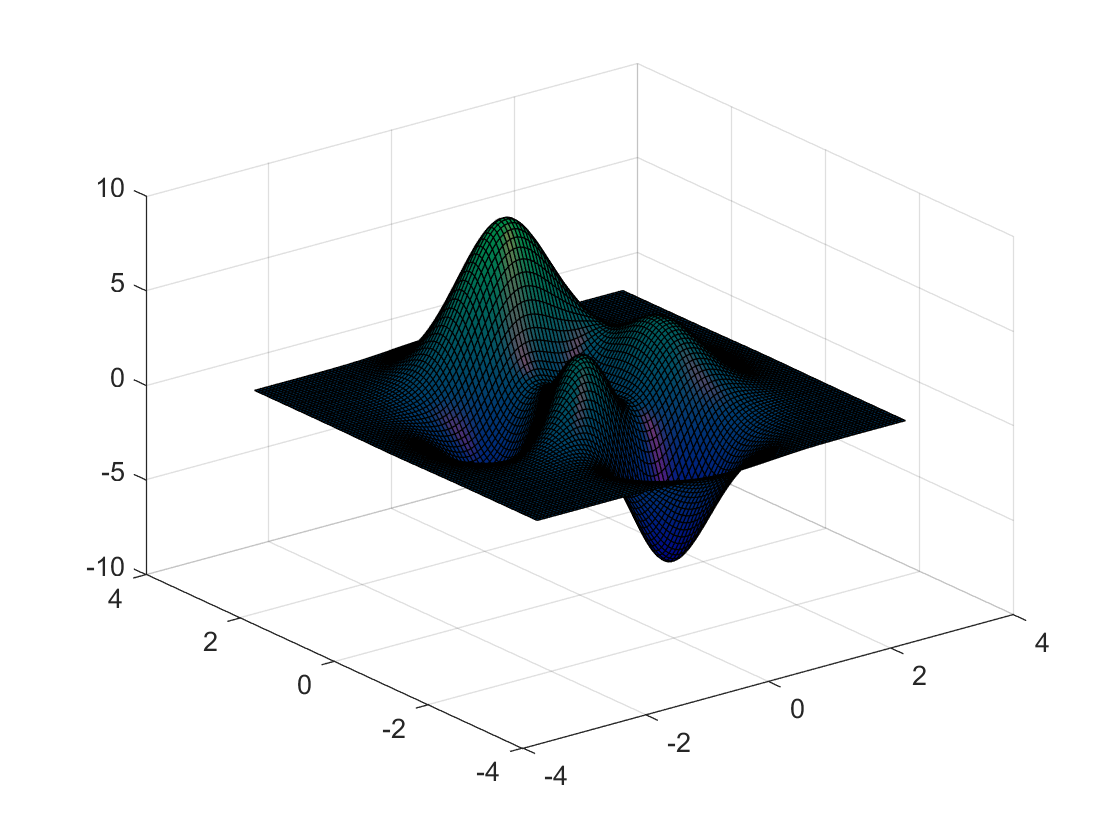

colormap("winter"); % Specify colormap

### Specify Light Direction and Reflectance

Specify the direction of the light source with azimuth and elevation parameters. 

Change the reflectance of the surface by specifying the contribution of ambient light, diffused reflection, specular reflection and the specular shine coefficient. 

Reduce edge transparency with the *EdgeAlpha* property to better visualize lighting changes.

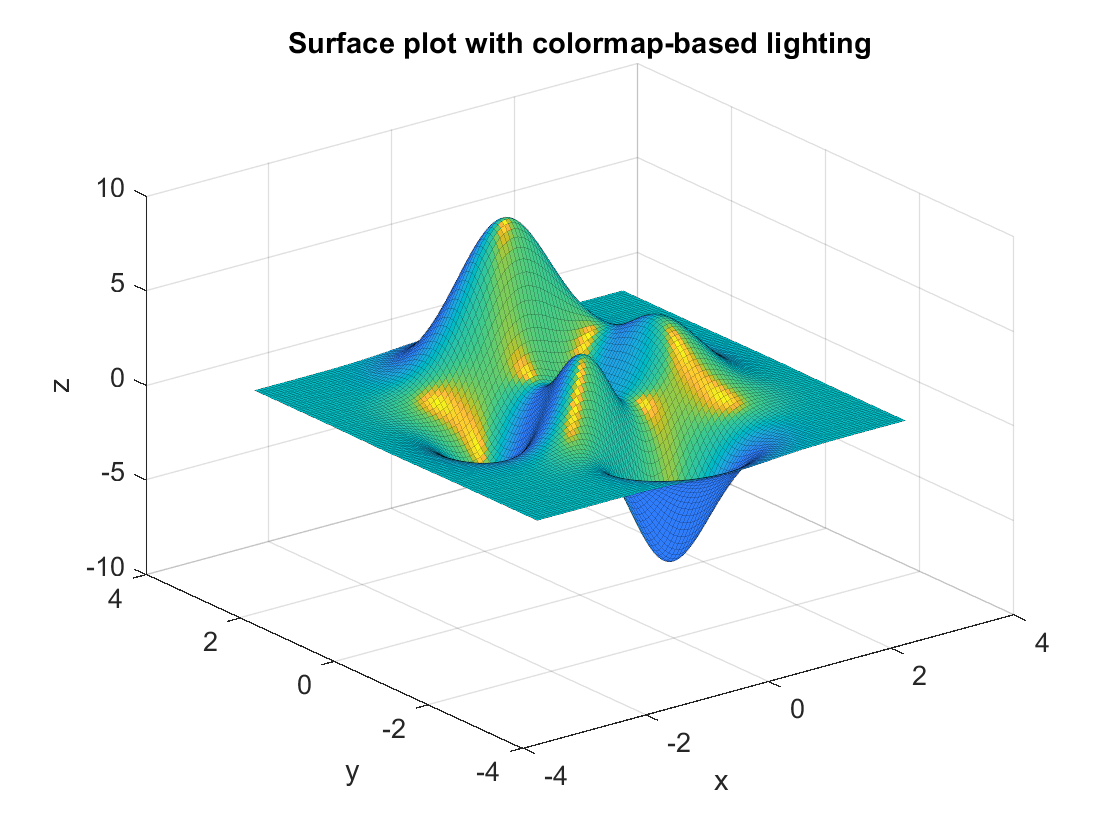

% Specify light direction parameters
azimuth = -10;
elevation = 35;

% Specify Reflectance Parameters
kAmb =0.4;
kDif =0.6;
kSpec =0.55;
kShine =8;
s = [azimuth elevation];
k = [kAmb kDif kSpec kShine];

figure
sl2 = surfl(X,Y,Z,s,k); % Specify light direction and reflectance parameters in function call
sl2.EdgeAlpha = 0.2;    % Reduce edge transparency 
colormap(parula);       % Use default colormap

xlabel("x"); ylabel("y"); zlabel("z");
title("Surface plot with colormap-based lighting")

## **Additional Information**

### **Get All Surface and Light Properties **

Graphics objects in MATLAB have many properties. To see all the properties of a Surface or Light, uncomment the following code. View or modify these properties using dot notation.

% get(sl(1)) % Surface
% get(sl(2)) % Light

### Documentation

Follow the link below to go to the documentation page to learn about the plot type in detail.

[surfl](https://www.mathworks.com/help/matlab/ref/surfl.html)

Copyright (c) 2021, The MathWorks, Inc.